**Load images**

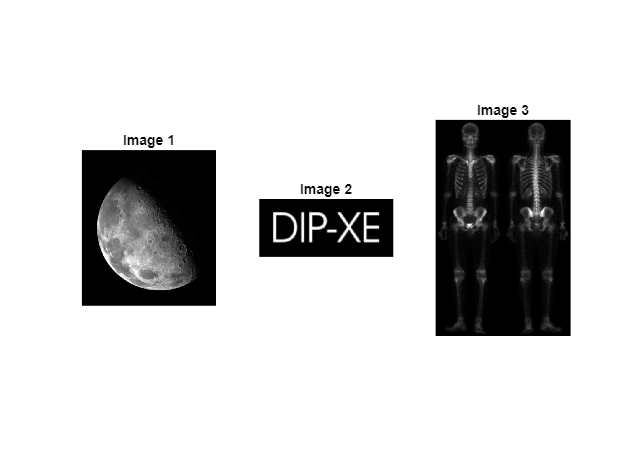

blurry_moon = imread('Fig0338(a)(blurry_moon).tif');
dipxe_text = imread('Fig0340(a)(dipxe_text).tif');
skeleton_orig = imread('Fig0343(a)(skeleton_orig).tif');

figure;
subplot(1, 3, 1);
imshow(blurry_moon, []);
title('Image 1');

subplot(1, 3, 2);
imshow(dipxe_text, []);
title('Image 2');

subplot(1, 3, 3);
imshow(skeleton_orig, []);
title('Image 3');

**Laplacian Filter for Edge Detection (blurry_moon)**

laplacian_filter = fspecial('laplacian');
laplacian_image = imfilter(blurry_moon, laplacian_filter);

**Sharpen the image by subtracting the Laplacian from the original image**

sharpened_image = blurry_moon - laplacian_image;

**Plot Laplacian output and sharpened image**

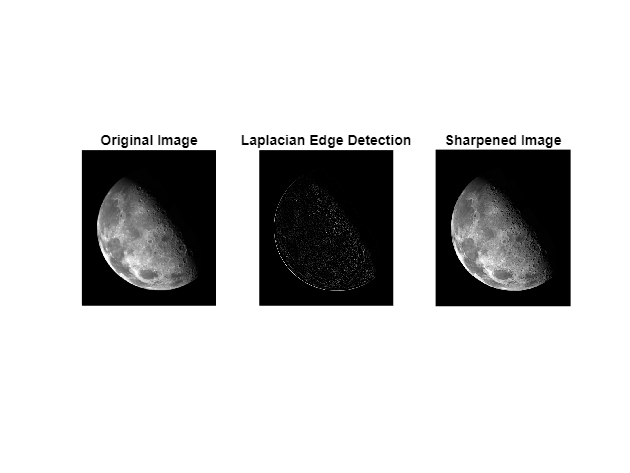

figure;
subplot(1, 3, 1);
imshow(blurry_moon, []);
title('Original Image');

subplot(1, 3, 2);
imshow(laplacian_image, []);
title('Laplacian Edge Detection');

subplot(1, 3, 3);
imshow(sharpened_image, []);
title('Sharpened Image');

**Unsharp Masking (dipxe_text)**

Apply Gaussian blur to the image (sigma = 3)

gaussian_blurred = imgaussfilt(dipxe_text, 3);

**Subtract the blurred image from the original to get the mask**

mask = dipxe_text - gaussian_blurred;

**Sharpen the image by adding the mask to the original**

unsharp_masked_image = dipxe_text + mask;

**Plot the original and sharpened images**

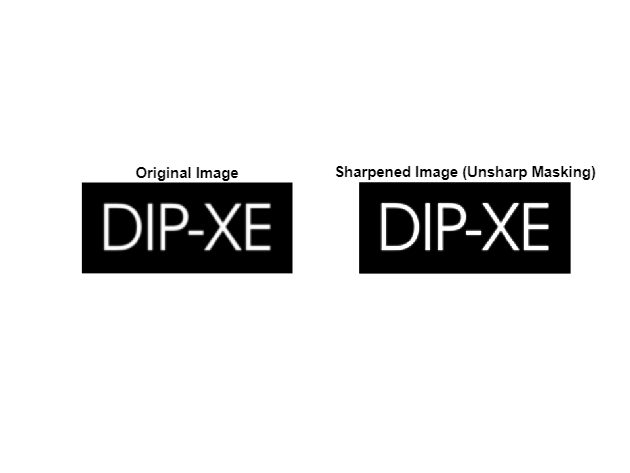

figure;
subplot(1, 2, 1);
imshow(dipxe_text, []);
title('Original Image');

subplot(1, 2, 2);
imshow(unsharp_masked_image, []);
title('Sharpened Image (Unsharp Masking)');

**Edge Detection Algorithms (skeleton_orig)**

Sobel Edge Detection

sobel_x = [-1 0 1; -2 0 2; -1 0 1];
sobel_y = [-1 -2 -1; 0 0 0; 1 2 1];

gradient_x = imfilter(double(skeleton_orig), sobel_x);
gradient_y = imfilter(double(skeleton_orig), sobel_y);
sobel_edge = sqrt(gradient_x.^2 + gradient_y.^2);

Prewitt Edge Detection

prewitt_x = [-1 0 1; -1 0 1; -1 0 1];
prewitt_y = [-1 -1 -1; 0 0 0; 1 1 1];

gradient_x_prewitt = imfilter(double(skeleton_orig), prewitt_x);
gradient_y_prewitt = imfilter(double(skeleton_orig), prewitt_y);
prewitt_edge = sqrt(gradient_x_prewitt.^2 + gradient_y_prewitt.^2);

Canny Edge Detection (using built-in function for comparison)

edges_canny = edge(skeleton_orig, 'Canny');

**Plot Sobel, Prewitt, and Canny edge detection results**

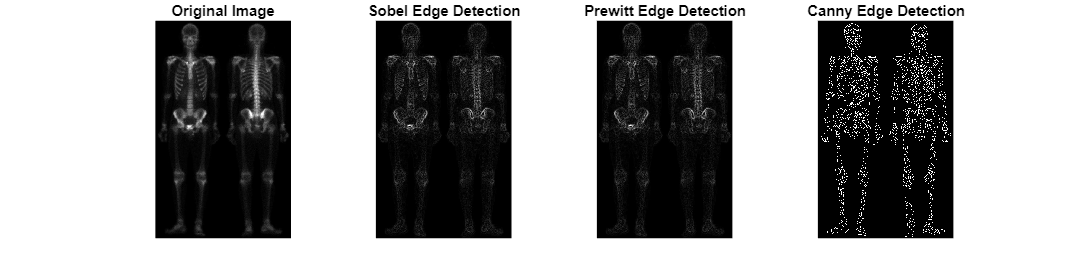

figure;
subplot(1, 4, 1);
imshow(skeleton_orig, []);
title('Original Image');

subplot(1, 4, 2);
imshow(sobel_edge, []);
title('Sobel Edge Detection');

subplot(1, 4, 3);
imshow(prewitt_edge, []);
title('Prewitt Edge Detection');

subplot(1, 4, 4);
imshow(edges_canny, []);
title('Canny Edge Detection');

set(gcf, 'Position', [100, 100, 1600, 400]);